# IMPORT DATA

close all
clc
clear all

dir = pwd;
wind_data = readtable(strcat(dir, '\Data\Wind_data.csv')).WindSpeed_m_s_;    %already access the table

Remove NaN from data

wind_data = wind_data(~isnan(wind_data));

Turbine data

rho_air = 1.225;            % air density [kg/m3]
H = 119;                    % hub height [m]
R_rotor = 178.3/2;               % rotor radius [m]
A_rotor = pi*R_rotor^2;     % rotor area [m2]
V_rated = 11.4;               % rated wind speed [m/s]
V_ci = 4;                   % cut-in wind speed [m/s]
V_co = 25;
Jeq = 1.56e8;                % equivalent inertia [kg*m2]
b = 2e5;                  % damping (equivalent losses) coefficient [N*m*s/rad]



% Cp-lambda curve
CpL = load(strcat(dir, '\Data\Cp_Burton.csv'));
Cp = spline(CpL(:, 1), CpL(:, 2));
ppval(Cp, 3) %test

ans = 0.1250

## PDF ANALYSYS

Calculate number of bins to use with Sturges' formula

n_bins = ceil(1 + log2(length(wind_data)))

n_bins = 18

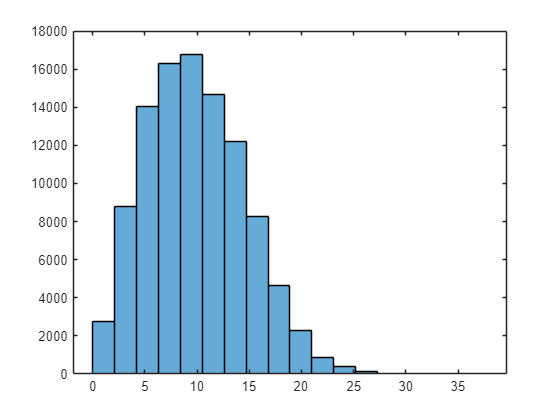


histogram(wind_data, n_bins)

Now we can fit the weibull distribution. No confidence interval is specified so it will be assumed to 95%

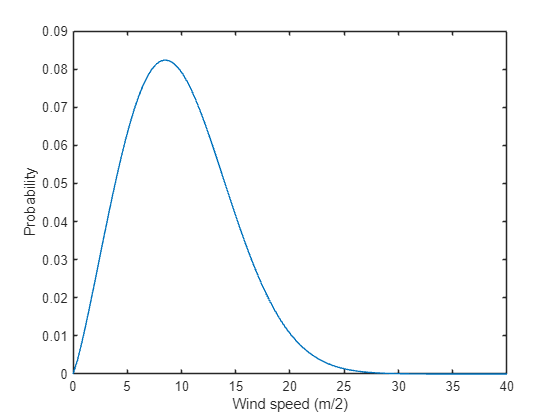

weibull_coeff = wblfit(wind_data);

x = linspace(0, 40);
plot(x, wblpdf(x, weibull_coeff(1), weibull_coeff(2)))
xlabel('Wind speed (m/2)')
ylabel('Probability')

## Stall regulated turbine

Constant speed, no pitch control.

Find the proper rotation speed omega. We can find this by imposing the lambda at which we have max Cp (usually at Cp = 0.45) and by imposing the wind speed as the AVERAGE wind speed of the year. In this way we have the max power extraction for most of the time

%% find lambda: we start by sampling the cp function, calculate its max and see at which lambda refers to
lambda_sweep = (0.1:0.1:18)';
Cp_sweep = ppval(Cp, lambda_sweep);
index = find(Cp_sweep == max(Cp_sweep));
lambda_stall_ideal = lambda_sweep(index);

%% Calculate turbine rotation speed
omega_stall_ideal = (mean(wind_data) * lambda_stall_ideal)/R_rotor;
omega_stall_ideal2 = (V_rated * lambda_stall_ideal)/R_rotor;

Now we have the ideal rotation speed. At this point we can calculate what is the tip speed ratio needed to maintain the ideal rotation speed as function of the wind speed.

lambda_stall = (omega_stall_ideal * R_rotor) ./ wind_data;
Cp_stall = ppval(Cp, lambda_stall);